format short;
addpath(genpath('mr')); % we use function library by Kevin Lynch / мы используем библиотеку функций Кевина Линча
syms q1 q2 q3 q4 q5 q6 q7 dq1 dq2 dq3 fx fy fz
syms l1 l2 l3 l4 l5 l6 m1 m2 m3 jx1 jy1 jz1 jx2 jy2 jz2 jx3 jy3 jz3 g 

Обобщенные координаты - это углы поворота, dq обозначает угловые скорости

q = [q1, q2, q3]; 
dq = [dq1, dq2, dq3];

Векторы единичных угловых скоростей

w1=[0;0;1]

w1 =      0
     0
     1


w2=[1;0;0]

w2 =      1
     0
     0


w3=[1;0;0]

w3 =      1
     0
     0


Расположение джоинтов (радиусы векторы до солченений от frame)

r1=[0;0;0]

r1 =      0
     0
     0


r2=[0;0;l1]

$$r2 = \left(\begin{array}{c} 0\\ 0\\ l_{1} \end{array}\right)$$

r3=[0;l2;l1]

$$r3 = \left(\begin{array}{c} 0\\ l_{2}\\ l_{1} \end{array}\right)$$

Vectors of translation motion / Векторы поступательного движения

v1_unit=-VecToso3(w1)*r1; 
% VecToso3 is a function from mr for skew-symmetric representation
% VecToso3 является функцией из mr для кососимметричного представления
v2_unit=-VecToso3(w2)*r2;
v3_unit=-VecToso3(w3)*r3;

Unit twists or screws the links / Винтовые оси для звеньев

S1=[w1;v1_unit];
S2=[w2;v2_unit];
S3=[w3;v3_unit];

Home position of CoM and ee / Изначальные положения для центром масс и энд-эффектора

Here by Hc10 I have denoted $H_{c_1}^{0}$. Тут под Hc10 понимается $H_{c_1}^{0}$

Hc10_home=[eye(3,3), [0;0;l1/2];  0,0,0,1]

$$Hc10\_home = \left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & 1 & 0 & 0\\ 0 & 0 & 1 & \frac{l_{1}}{2}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Hc20_home=[eye(3,3), [0;l2/2;l1];  0,0,0,1]

$$Hc20\_home = \left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & 1 & 0 & \frac{l_{2}}{2}\\ 0 & 0 & 1 & l_{1}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Hc30_home=[eye(3,3), [0;l2+l3/2;l1];  0,0,0,1]

$$Hc30\_home = \left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & 1 & 0 & l_{2}+\frac{l_{3}}{2}\\ 0 & 0 & 1 & l_{1}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

Hee0_home=[eye(3,3), [0;l2+l3;l1];  0,0,0,1]

$$Hee0\_home = \left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & 1 & 0 & l_{2}+l_{3}\\ 0 & 0 & 1 & l_{1}\\ 0 & 0 & 0 & 1 \end{array}\right)$$

#### Rotation matrixes / Матрицы поворота


$$R=e^{\tilde{w}}=I+\tilde{w}\sin{\theta}+\tilde{w}^2(1-\cos{\theta})$$


In code by Rij I have denoted $R_i^j$ / В коде под Rij я обозначил$R_i^j$

R10=eye(3,3)+VecToso3(w1)*sin(q1)+VecToso3(w1)^2*(1-cos(q1)) % matrix exponential rodrigues formula

$$R10 = \left(\begin{array}{ccc} \cos\left(q_{1}\right) & -\sin\left(q_{1}\right) & 0\\ \sin\left(q_{1}\right) & \cos\left(q_{1}\right) & 0\\ 0 & 0 & 1 \end{array}\right)$$

R21=eye(3,3)+VecToso3(w2)*sin(q2)+VecToso3(w2)^2*(1-cos(q2)); 
R32=eye(3,3)+VecToso3(w3)*sin(q3)+VecToso3(w3)^2*(1-cos(q3)); 

#### Homogeneous transformation matrixes / Однородная матрица преобразования 

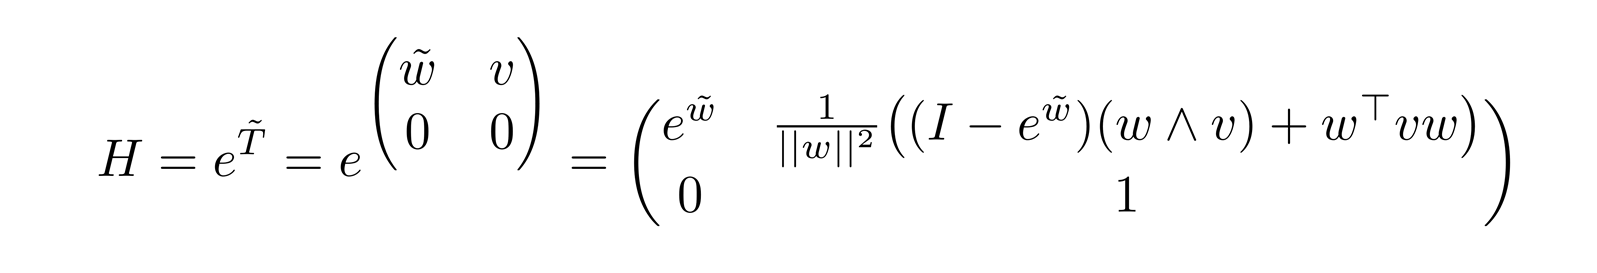

abs_ter_1=(eye(3,3)*q1+(1-cos(q1))*VecToso3(w1)+(q1-sin(q1))*VecToso3(w1)^2)*v1_unit;
abs_ter_2=(eye(3,3)*q2+(1-cos(q2))*VecToso3(w2)+(q2-sin(q2))*VecToso3(w2)^2)*v2_unit;
abs_ter_3=(eye(3,3)*q3+(1-cos(q3))*VecToso3(w3)+(q3-sin(q3))*VecToso3(w3)^2)*v3_unit;

Here by T100 I have denoted $T_1^{0,0}$

e_T100q1=[R10, abs_ter_1; 0,0,0,1];
e_T201q2=[R21, abs_ter_2; 0,0,0,1];
e_T302q3=[R32, abs_ter_3; 0,0,0,1]

$$e\_T302q3 = \left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & \cos\left(q_{3}\right) & -\sin\left(q_{3}\right) & l_{1}\,\sin\left(q_{3}\right)-l_{2}\,\left(\cos\left(q_{3}\right)-1\right)\\ 0 & \sin\left(q_{3}\right) & \cos\left(q_{3}\right) & -l_{2}\,\sin\left(q_{3}\right)-l_{1}\,\left(\cos\left(q_{3}\right)-1\right)\\ 0 & 0 & 0 & 1 \end{array}\right)$$

#### Direct kinematics / Прямая кинематика


$$H_n^0 (q_1, q_2, \dots q_n)=
e^{\tilde{\hat{T}}_1^{0,0}q_1} e^{\tilde{\hat{T}}_2^{0,1}q_2} \dots
e^{\tilde{\hat{T}}_n^{0,(n-1)}q_n} H_n^{0}(0),
$$


Hc10=simplify(e_T100q1*Hc10_home);
Hc20=simplify(e_T100q1*e_T201q2*Hc20_home);
Hc30=simplify(e_T100q1*e_T201q2*e_T302q3*Hc30_home);
Hee0=simplify(e_T100q1*e_T201q2*e_T302q3*Hee0_home);
P=Hee0*[0;0;0;1]

$$P = \left(\begin{array}{c} -\sin\left(q_{1}\right)\,\left(l_{3}\,\cos\left(q_{2}+q_{3}\right)+l_{2}\,\cos\left(q_{2}\right)\right)\\ \cos\left(q_{1}\right)\,\left(l_{3}\,\cos\left(q_{2}+q_{3}\right)+l_{2}\,\cos\left(q_{2}\right)\right)\\ l_{1}+l_{3}\,\sin\left(q_{2}+q_{3}\right)+l_{2}\,\sin\left(q_{2}\right)\\ 1 \end{array}\right)$$


Hc01=TransInv(Hc10);
Hc02=TransInv(Hc20);
Hc03=TransInv(Hc30);
H0ee=TransInv(Hee0)

$$H0ee = \begin{array}{l} \left(\begin{array}{cccc} \cos\left(q_{1}\right) & \sin\left(q_{1}\right) & 0 & 0\\ -\cos\left(q_{2}+q_{3}\right)\,\sin\left(q_{1}\right) & \cos\left(q_{2}+q_{3}\right)\,\cos\left(q_{1}\right) & \sin\left(q_{2}+q_{3}\right) & -\cos\left(q_{2}+q_{3}\right)\,\sigma_{1}\,{\cos\left(q_{1}\right)}^{2}-\cos\left(q_{2}+q_{3}\right)\,\sigma_{1}\,{\sin\left(q_{1}\right)}^{2}-\sin\left(q_{2}+q_{3}\right)\,\sigma_{2}\\ \sin\left(q_{2}+q_{3}\right)\,\sin\left(q_{1}\right) & -\sin\left(q_{2}+q_{3}\right)\,\cos\left(q_{1}\right) & \cos\left(q_{2}+q_{3}\right) & \sin\left(q_{2}+q_{3}\right)\,\sigma_{1}\,{\cos\left(q_{1}\right)}^{2}+\sin\left(q_{2}+q_{3}\right)\,\sigma_{1}\,{\sin\left(q_{1}\right)}^{2}-\cos\left(q_{2}+q_{3}\right)\,\sigma_{2}\\ 0 & 0 & 0 & 1 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=l_{3}\,\cos\left(q_{2}+q_{3}\right)+l_{2}\,\cos\left(q_{2}\right)\\ \sigma_{2}=l_{1}+l_{3}\,\sin\left(q_{2}+q_{3}\right)+l_{2}\,\sin\left(q_{2}\right) \end{array}$$

TransInv is a function from mr to take an inverse of H / TransInv - это функция от mr чтобы брать обратную от  H

#### Geometriacal Jacobians / Геометрические матрицы якоби

J1=S1;
J2=simplify(Adjoint(e_T100q1*e_T201q2)*S2);
J3=simplify(Adjoint(e_T100q1*e_T201q2*e_T302q3)*S3);
J_1=[J1, zeros(6,1), zeros(6,1)];
J_2=[J1, J2, zeros(6,1)];
J_3=[J1, J2, J3]

$$J\_3 = \left(\begin{array}{ccc} 0 & \cos\left(q_{1}\right) & \cos\left(q_{1}\right)\\ 0 & \sin\left(q_{1}\right) & \sin\left(q_{1}\right)\\ 1 & 0 & 0\\ 0 & -l_{1}\,\sin\left(q_{1}\right) & -\sin\left(q_{1}\right)\,\left(l_{1}+l_{2}\,\sin\left(q_{2}\right)\right)\\ 0 & l_{1}\,\cos\left(q_{1}\right) & \cos\left(q_{1}\right)\,\left(l_{1}+l_{2}\,\sin\left(q_{2}\right)\right)\\ 0 & 0 & -l_{2}\,\cos\left(q_{2}\right) \end{array}\right)$$

Coordinates of CoM / z координаты центров масс

zc1=[0, 0, 1, 0]*Hc10*[0;0;0;1];
zc2=[0, 0, 1, 0]*Hc20*[0;0;0;1];
zc3=[0, 0, 1, 0]*Hc30*[0;0;0;1]

$$zc3 = l_{1}+\frac{l_{3}\,\sin\left(q_{2}+q_{3}\right)}{2}+l_{2}\,\sin\left(q_{2}\right)$$

Inertia / инерция

j1=[jx1, 0, 0; 0, jy1, 0; 0, 0, jz1];
j2=[jx2, 0, 0; 0, jy2, 0; 0, 0, jz2];
j3=[jx3, 0, 0; 0, jy3, 0; 0, 0, jz3];
I1=[j1, zeros(3,3); zeros(3,3), eye(3,3)*m1];
I2=[j2, zeros(3,3); zeros(3,3), eye(3,3)*m2];
I3=[j3, zeros(3,3); zeros(3,3), eye(3,3)*m3]

$$I3 = \left(\begin{array}{cccccc} {\mathrm{jx}}_{3} & 0 & 0 & 0 & 0 & 0\\ 0 & {\mathrm{jy}}_{3} & 0 & 0 & 0 & 0\\ 0 & 0 & {\mathrm{jz}}_{3} & 0 & 0 & 0\\ 0 & 0 & 0 & m_{3} & 0 & 0\\ 0 & 0 & 0 & 0 & m_{3} & 0\\ 0 & 0 & 0 & 0 & 0 & m_{3} \end{array}\right)$$

#### Mass matrix and other terms of dynamic equation / Матрица массы и другие члены динамического уравнения

M_1 = simplify(J_1.'*Adjoint(Hc01).'*I1*Adjoint(Hc01)*J_1);
M_2 = simplify(J_2.'*Adjoint(Hc02).'*I2*Adjoint(Hc02)*J_2);
M_3 = simplify(J_3.'*Adjoint(Hc03).'*I3*Adjoint(Hc03)*J_3);
M = M_1+M_2+M_3

$$M = \begin{array}{l} \left(\begin{array}{ccc} \frac{{\mathrm{jy}}_{2}}{2}+\frac{{\mathrm{jy}}_{3}}{2}+{\mathrm{jz}}_{1}+\frac{{\mathrm{jz}}_{2}}{2}+\frac{{\mathrm{jz}}_{3}}{2}-\frac{{\mathrm{jy}}_{3}\,\sigma_{1}}{2}+\frac{{\mathrm{jz}}_{3}\,\sigma_{1}}{2}+\frac{{l_{2}}^{2}\,m_{2}}{8}+\frac{{l_{2}}^{2}\,m_{3}}{2}+\frac{{l_{3}}^{2}\,m_{3}}{8}-\frac{{\mathrm{jy}}_{2}\,\cos\left(2\,q_{2}\right)}{2}+\frac{{\mathrm{jz}}_{2}\,\cos\left(2\,q_{2}\right)}{2}+\frac{{l_{2}}^{2}\,m_{2}\,\cos\left(2\,q_{2}\right)}{8}+\frac{{l_{2}}^{2}\,m_{3}\,\cos\left(2\,q_{2}\right)}{2}+\frac{{l_{3}}^{2}\,m_{3}\,\sigma_{1}}{8}+\frac{\sigma_{2}}{2}+\frac{l_{2}\,l_{3}\,m_{3}\,\cos\left(2\,q_{2}+q_{3}\right)}{2} & 0 & 0\\ 0 & {\mathrm{jx}}_{2}+{\mathrm{jx}}_{3}+\frac{{l_{2}}^{2}\,m_{2}}{4}+{l_{2}}^{2}\,m_{3}+\frac{{l_{3}}^{2}\,m_{3}}{4}+\sigma_{2} & \sigma_{3}\\ 0 & \sigma_{3} & \sigma_{4}+{\mathrm{jx}}_{3} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\cos\left(2\,q_{2}+2\,q_{3}\right)\\ \sigma_{2}=l_{2}\,l_{3}\,m_{3}\,\cos\left(q_{3}\right)\\ \sigma_{3}=\sigma_{4}+\frac{l_{2}\,m_{3}\,\cos\left(q_{3}\right)\,l_{3}}{2}+{\mathrm{jx}}_{3}\\ \sigma_{4}=\frac{m_{3}\,{l_{3}}^{2}}{4} \end{array}$$


V = simplify(m1*g*zc1+m2*g*zc2+m3*g*zc3);
N = simplify([diff(V,q1); diff(V,q2); diff(V,q3)])

$$N = \left(\begin{array}{c} 0\\ g\,m_{3}\,\left(\frac{l_{3}\,\cos\left(q_{2}+q_{3}\right)}{2}+l_{2}\,\cos\left(q_{2}\right)\right)+\frac{g\,l_{2}\,m_{2}\,\cos\left(q_{2}\right)}{2}\\ \frac{g\,l_{3}\,m_{3}\,\cos\left(q_{2}+q_{3}\right)}{2} \end{array}\right)$$

C = simplify(getC(M, q ,dq))

$$C = \begin{array}{l} \left(\begin{array}{c} {\mathrm{dq}}_{1}\,\left(\frac{{\mathrm{jz}}_{3}\,\sigma_{1}}{2}-\frac{{\mathrm{jy}}_{3}\,\sigma_{1}}{2}+\frac{{l_{3}}^{2}\,m_{3}\,\sigma_{1}}{8}+\frac{l_{2}\,l_{3}\,m_{3}\,\sin\left(q_{3}\right)}{4}+\frac{l_{2}\,l_{3}\,m_{3}\,\sin\left(2\,q_{2}+q_{3}\right)}{4}\right)\\ \frac{{\mathrm{dq}}_{2}\,l_{2}\,l_{3}\,m_{3}\,\sin\left(q_{3}\right)}{2}\\ 0 \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\sin\left(2\,q_{2}+2\,q_{3}\right) \end{array}$$

Wrench / Пространственный ко-вектор внешней нагрузки

W = [0, 0, 0, fx, fy, fz];

Joints' torque / Момент на сочленениях

tau = simplify(J_3.'*Adjoint(H0ee).'*W.');

function [C] = getC(M, q, dq)

    n = size(M, 1);
    G = sym(zeros(n, n, n)); % cristofil symbol G_ijk
   
    for i = 1:n
        for j = 1:n
            for k = 1:n
                G(i, j, k) =  sym(1/2) * (diff(M(i, j), q(k)) + diff(M(i, k), q(j)) - diff(M(k, j), q(i)));
            end
        end
    end

    C = sym(zeros(n, 1)); % coriolis and centrifugal C = \sum c_{ijk} \dot{q}_i
         for j = 1:n
            sum = 0;
            for k = 1:n
                sum = sum + G(i, j, k) * dq(k);
         end
    C(j) = sum;
    end
end